# Invariant Transformation of Maddern

## What is it?

The invariant Maddern transform is a method that generates images invariant to changes in illumination, reducing the influence of shadows and variations in light intensity. It is based on a spectrum model of the camera sensor and incident light.

## Basic operation of the transformation

**1. Relationship between color channels:**

Given a camera with spectral sensitivity $F(\lambda) $, the model response of a specific channel $R$ to light of a particular wavelength $\lambda$ is defined as:


$$R^{x,E} = a^x \cdot n^x \cdot I^x \int S^x(\lambda) E(\lambda) F(\lambda) d\lambda$$


where:

- $a^x$ y $n^x$: vectors representing the direction of light and the surface normal.

- $I^x$: light intensity at point $x$.

- $S^x(\lambda)$: spectral reflectance of the surface.

- $E(\lambda)$: spectrum of the light source.

**2. Logarithmic-chromatic space:**

The relationships of the color channels are transformed to the logarithmic-chromatic space by taking the logarithm of the spectral response:


$$\log(R^{x,E}) = \log (G^x I^x) + \log S^x (\lambda_i) + \log E^x (\lambda_i)$$


where:

- $G^x=a^x \cdot n^x$ represents the geometry between the light and the scene.

**3. Invariant projection:**

The spectral responses are projected in a specific direction that eliminates the illumination component. The final projection in direction $\alpha$ is made using:


$$I = \log (R_2) - \alpha \log (R_1) - (1 - \alpha) \log (R_3)
$$


where:

- $R_1, R_2, R_3$: spectral responses of three color channels (e.g. $R, G, B$).

- $\alpha$: parameter determined by the spectral sensitivities of the channels.

**4. Calculation of parameter **$\alpha$**:**

The parameter $\alpha$ is calculated to ensure that the projection is independent of the color temperature $T$ of the light:


$$\frac{1}{\lambda_2} = \frac{\alpha}{\lambda_1} + \frac{1 - \alpha}{\lambda_3}$$


**5. Maddern invariant transformation:**

Finally, the following transformation is applied to obtain an invariant image:


$$I_{Maddern} = 0.5 + \log(G) - \alpha \log(B) - (1 - \alpha) \log(R)$$


## Implementation analysis:

**1. Input parameters:**

- $RGB$: image in RGB format.

- $alpha$: parameter for logarithmic approximation.

**2. Separation of channels:**

First, the function saves each image channel, $R$, $G$ and $B$, separately..

R = double(RGB(:,:,1));
G = double(RGB(:,:,2));
B = double(RGB(:,:,3));

**3. Calculation of parameter **$\alpha$

The parameter $\alpha

$ is canceled in a separate function and passed as a parameter.

alpha = (lambda3 / (lambda3 - lambda1)) * (1/lambda2 - 1/lambda3);

**4. Invariant transformation:**

Finally, the function performs the invariant transformation with parameter $\alpha$:

I_Maddern = 0.5 + log(G) - alpha*log(B) - (1 - alpha)*log(R);

### Complete code

function alpha = calcular_alpha(lambda1, lambda2, lambda3)
    alpha = (lambda3 / (lambda3 - lambda1)) * (1/lambda2 - 1/lambda3);
end

function I_Maddern = maddern_transform(RGB, alpha)
    % Separation of the RGB image by double channels
    R = double(RGB(:,:,1));
    G = double(RGB(:,:,2));
    B = double(RGB(:,:,3));
    
    % Invariant transformation
    I_Maddern = 0.5 + log(G) - alpha*log(B) - (1 - alpha)*log(R);
end

An example of a program image and its corresponding transformation:

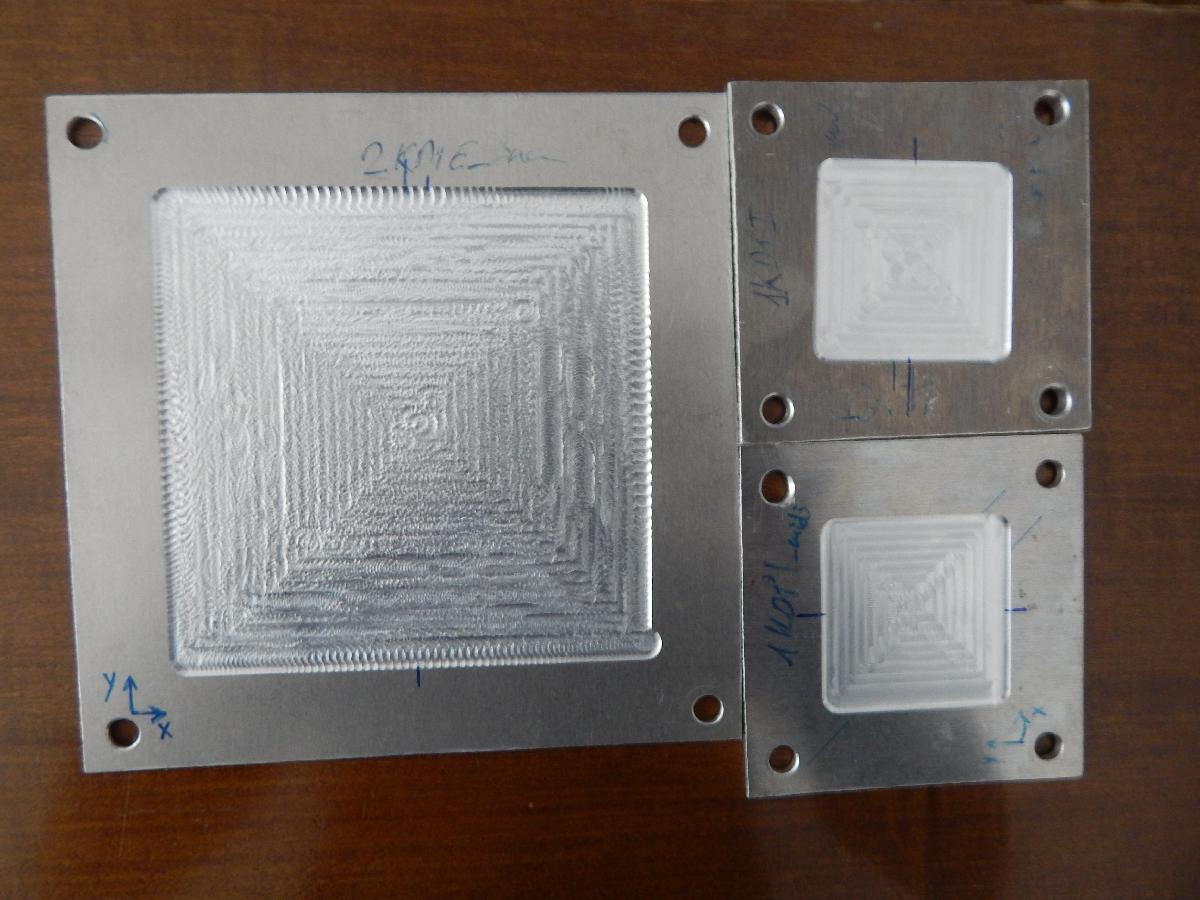    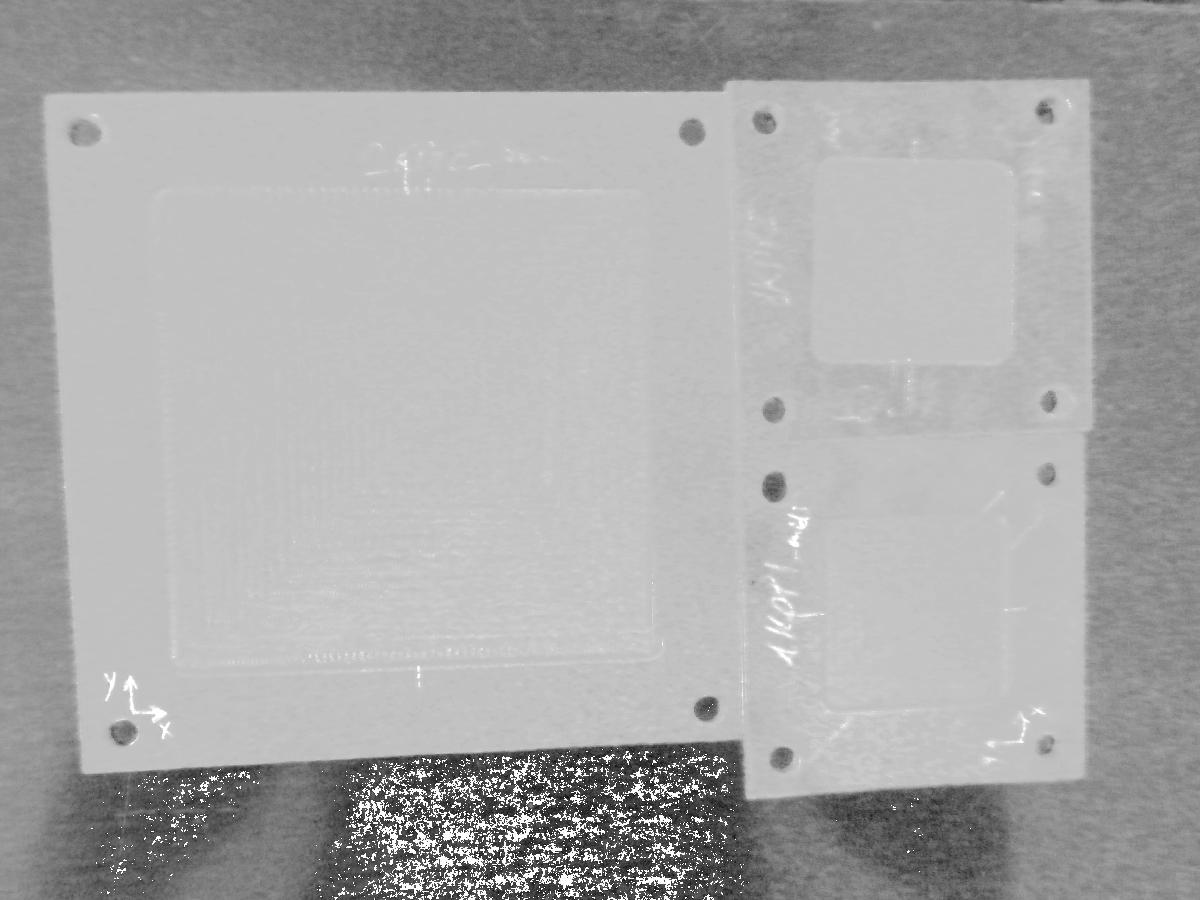

## References

- Maddern, W., Stewart, A. D., McManus, C., Upcroft, B., Churchill, W., & Newman, P. "Illumination invariant imaging: Applications in robust vision-based localisation, mapping and classification for autonomous vehicles," IEEE Intelligent Transportation Systems (ITSC), pp. 328-335, 2014.